# `Typical Utility Functions for 2-period economy`

# 2D Utility function (xy-plane)

## Log utility

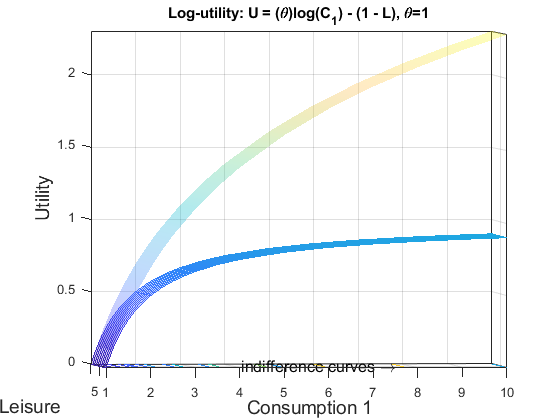

thet=2;
syms C1 C2
% U = @(C1,L) thet*log(C1) + log(L);

Ulog = @(C1) log(C1);
Uces = @(C2) ((C2).^(1-thet) - 1)./(1 - thet);

%figure()
fsurf(Ulog, [1 10], 'MeshDensity', 10, 'ShowContours','on','edgecolor','none')
%view(60,20)
hold on
fsurf(Uces, [1 10], 'MeshDensity', 10, 'ShowContours','on','edgecolor','interp')

xlabel('Consumption 1','FontSize',14)
% ylabel('Consumption 2','FontSize',14)
ylabel('Leisure','FontSize',14)
zlabel('Utility','FontSize',14)

alpha(0.3)
shading interp


% %bottom triangle
% UX = [3.8; 1; 3.8];
% UY = [1; 6; 1];
% UZ = [1; 1 ; 6];
% %top triangle
% UX1 = [6.33; 1; 6.33];
% UY1 = [1; 10; 1];
% UZ1 = [1; 1 ; 6];
% %C specifies color
% UC = [0.5000 ;
%      1.0000 ;
%      0.3330 ];

hold on
%figure
% fill3(UX,UY,UZ,UC)
% %figure
% fill3(UX1,UY1,UZ1,UC)
%view(60,20)
% view(2)
%view(20,60)
% view(90,90)
box on
grid on

% text(5.3, 3,'\leftarrow budget constraint', 'fontsize', 12)
text(4.3, 8,'indifference curves \rightarrow', 'fontsize', 12)
title('Log-utility: U = (\theta)log(C_1) - (1 - L), \theta=1')

hold off

# 3D Utility functions (xyz-surface)

## Log Utility

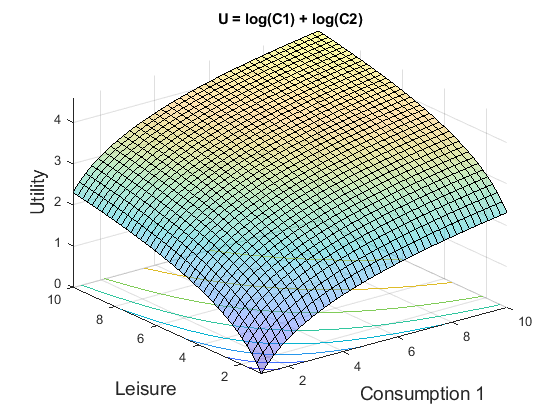

thetta=1;
syms C1 C2
%U = (C1^(1-thetta)/(1-thetta))
LogU1 = thetta*log(C1) + log(L);
fsurf(LogU1, [1 10], 'MeshDensity', 40, 'ShowContours','on')
%view(60,20)
xlabel('Consumption 1','FontSize',14)
% ylabel('Consumption 2','FontSize',14)
ylabel('Leisure','FontSize',14)
zlabel('Utility','FontSize',14)
title('U = log(C1) + log(C2)')

alpha(0.4) %transparency
shading interp

hold off

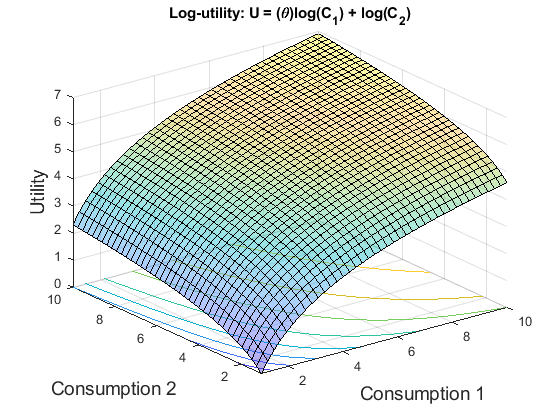


thetta2=2;
%syms C1 C2
%U = (C1^(1-thetta)/(1-thetta)).*C2 %U = thetta*log(C1) + log(C2)
LogU2 = thetta2*log(C1) + log(C2);
fsurf(LogU2, [1 10], 'MeshDensity', 40, 'ShowContours','on')
%view(60,20)
xlabel('Consumption 1','FontSize',14)
ylabel('Consumption 2','FontSize',14)
zlabel('Utility','FontSize',14)
title('Log-utility: U = (\theta)log(C_1) + log(C_2)')

alpha(0.4)
shading interp

hold off

## Cobb-Douglas Utility

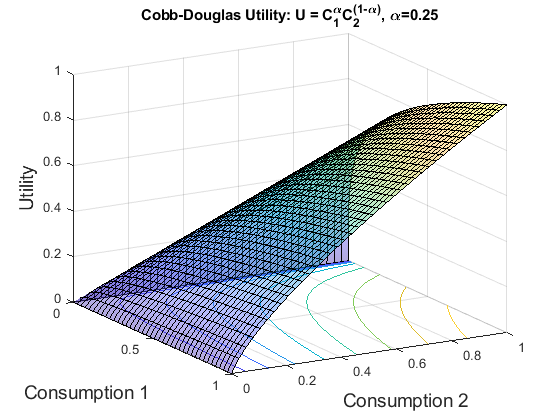

gam=1;
alppha1=0.25;
CDU1 = @(C1,C2) ((C1.^alppha1.*C2.^(1-alppha1)).^(gam))/(gam);
fsurf(CDU1, [0 1], 'MeshDensity', 40, 'ShowContours','on')
view(60,20)

xlabel('Consumption 1','FontSize',14)
ylabel('Consumption 2','FontSize',14)
zlabel('Utility','FontSize',14)
title('Cobb-Douglas Utility: U = C_1^{\alpha}C_2^{(1-\alpha)}, \alpha=0.25')

alpha(0.4) %transparency
shading interp

hold off

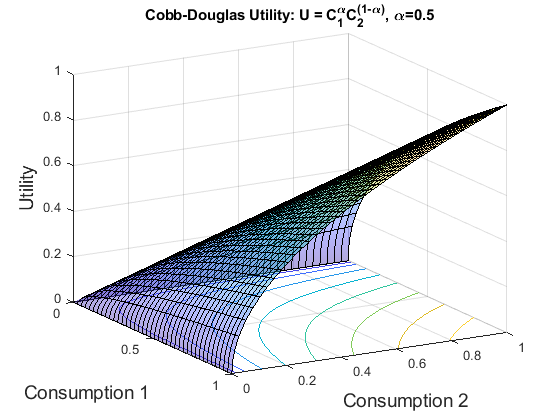

alppha2=0.5;
CDU2 = @(C1,C2) C1.^alppha2.*C2.^(1-alppha2);
fsurf(CDU2, [0 1], 'MeshDensity', 40, 'ShowContours','on')
view(60,20)

xlabel('Consumption 1','FontSize',14)
ylabel('Consumption 2','FontSize',14)
zlabel('Utility','FontSize',14)
title('Cobb-Douglas Utility: U = C_1^{\alpha}C_2^{(1-\alpha)}, \alpha=0.5')

alpha(0.4) %transparency
shading interp

hold off

# Utility with Budget Constraint

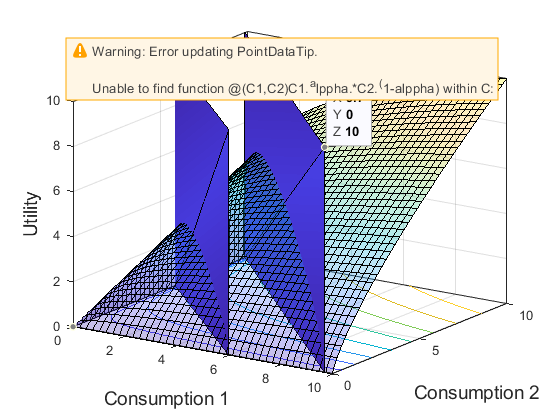

alppha=0.25;
U = @(C1,C2) C1.^alppha.*C2.^(1-alppha);
fsurf(U, [0 10], 'MeshDensity', 40, 'ShowContours','on')
view(60,20)

xlabel('Consumption 1','FontSize',14)
ylabel('Consumption 2','FontSize',14)
zlabel('Utility','FontSize',14)

hold on

alpha(0.3)
shading interp

%bottom triangle
UX = [6 0; 0 6; 6 0];
UY = [0 5.85; 5.85 0 ; 0 5.85];
UZ = [10 0 ; 0 10; 0 10]; 
     
%top triangle
UX1 = [9.7 0; 0 9.7; 9.7 0];
UY1 = [0 9.85; 9.85 0; 0 9.85];
UZ1 = [10 0; 0 10; 0 10];

%%% C specifies color
UC = [1 1;
     0.5 0.5;
     0 0];

%hold on
%figure
fill3(UX,UY,UZ,UC)
%figure
fill3(UX1,UY1,UZ1,UC)
view(33.9, 20.6)
%view(2)
%view(20,60)
box on
grid on
hold off

# Utility w/ BC

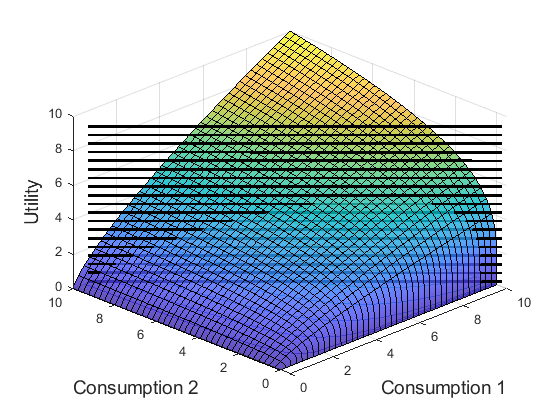

alppha=0.75;
U = @(C1,C2) C1.^alppha.*C2.^(1-alppha);
fsurf(U, [0 10], 'MeshDensity', 40, 'ShowContours','on')
view(60,20)

%hold on
%C1 = @(C1,C2) C2/(-(1+rate)) ;
%C2 = @(C1,C2) (-(1+rate))*C1 ;
%BC = @(C1,C2) C1 + C2/(1 + rate);  % - Q1 - Q2/(1+rate)
%Ut = @(C1,C2) C1;
%fsurf(BC, [0 10 0 10], 'MeshDensity', 40, 'ShowContours','on')
%view(110,30)

xlabel('Consumption 1','FontSize',14)
ylabel('Consumption 2','FontSize',14)
zlabel('Utility','FontSize',14)

hold on

Q1=5;
Q2=5;
rate=0.05;
PVwealth = Q1 + Q2./(1+rate);
%PVwealth = 10;

for i=1:0.5:10
syms x y z
x = - y./(1 + rate) + PVwealth; %x-intercept
y = - (1 + rate).*x + PVwealth; %y-intercept
z = x + y./(1 + rate) - PVwealth + i; %BC less PV of total wealth approx. zero plus "i levels"
fplot3(x,y,z,[0 10],'k', 'linewidth',2)
end
view([-45,35])

alpha(0.8) %transparency
shading interp
%grid off
%box off

hold off